# clear all; close all; clc;

S = RandStream("mt19937ar","Seed",5489); % Set the RNG for reproducibility
RandStream.setGlobalStream(S);

antennaSizes = [4, 2, 1];  % Antenna array lengths
chanBW = "CBW40";          % Fix bandwidth to 40 MHz

positioningErrors = cell(1, numel(antennaSizes));
localizationErrors = cell(1, numel(antennaSizes));
taskList = ["positioning", "localization"];

for antIdx = 1:numel(antennaSizes)
    txArraySize = [antennaSizes(antIdx), 1];
    rxArraySize = [antennaSizes(antIdx), 1];

end

distribution = "uniform";

if distribution == "uniform"
    val = 0.25;
    [APs,STAs] = dlPositioningCreateEnvironment(txArraySize,rxArraySize,val,"uniform");
else   
    numSTAs = 500; % Number of STAs for the random distribution
    [APs,STAs] = dlPositioningCreateEnvironment(txArraySize,rxArraySize,numSTAs,"random");
end

labels = string({STAs.Name});

unique_labels = unique(labels);
for i = 1:length(unique_labels)
    disp(unique_labels(i) + " count: " + sum(labels == unique_labels(i)));
end

conference_room count: 1760
desk1 count: 100
desk2 count: 220
desk3 count: 480
desk4 count: 80
office count: 440
storage count: 120



task = "localization";

mapFile = "layout.stl";

viewer = siteviewer("SceneModel",mapFile,"Transparency",0.25);

show(APs)
show(STAs,"ShowAntennaHeight",false,"IconSize",[16 16]);
disp(['Simulating a scenario with ',num2str(width(APs)),' APs and ',num2str(width(STAs)),' STAs with ',char(distribution),' distribution...'])

Simulating a scenario with 4 APs and 3200 STAs with uniform distribution...



pm = propagationModel("raytracing", ...
    "CoordinateSystem","cartesian", ...
    "SurfaceMaterial","wood", ...
    "MaxNumReflections",1);

% Perform ray tracing for all transmitters and receivers in parallel
rays = raytrace(APs,STAs,pm,"Map",mapFile);
size(rays)

ans =            4        3200



hide(STAs);
show(STAs(ceil(width(STAs)/2)),'IconSize',[32 32]);
plot([rays{:,ceil(width(rays)/2)}],'ColorLimits',[50 95]);


cfg = heRangingConfig('ChannelBandwidth','CBW40', ...
    "NumTransmitAntennas", prod(txArraySize), ...
    "SecureHELTF", false);
% Create a valid heRangingUser object
user = heRangingUser;
user.NumSpaceTimeStreams = prod(txArraySize);

% Assign it to the config
cfg.User = {user};  % <-- must be a cell array of user objects

txWaveform = single(heRangingWaveformGenerator(cfg));
snrs = [5 10 20 25];

[features, labels] = dlPositioningGenerateDataSet(rays, STAs, APs, cfg, snrs);

Generating Dataset: 10% complete.
Generating Dataset: 20% complete.
Generating Dataset: 30% complete.
Generating Dataset: 40% complete.
Generating Dataset: 50% complete.
Generating Dataset: 60% complete.
Generating Dataset: 70% complete.
Generating Dataset: 80% complete.
Generating Dataset: 90% complete.
Generating Dataset: 100% complete.



[training,validation] = dlPositioningSplitDataSet(features,labels,0.2);

layers = [
    
    imageInputLayer(size(training.X, 1:3))

    convolution2dLayer(3,256,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    averagePooling2dLayer(2,"Stride",2,"Padding","same")
    
    convolution2dLayer(3,256,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    averagePooling2dLayer(2,"Stride",2,"Padding","same")

    convolution2dLayer(3,256,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    averagePooling2dLayer(2,"Stride",2,"Padding","same")
  
    convolution2dLayer(3,256,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    averagePooling2dLayer(2,"Stride",2,"Padding","same")
   
    dropoutLayer(0.2)];

if task == "localization" % classification
    layers = [
        layers
        fullyConnectedLayer(7)
        softmaxLayer];
    lossFcn = "crossentropy";
    trainingMetric = "accuracy";
else % positioning (regression)
    layers = [
        layers
        fullyConnectedLayer(3)];
    lossFcn = "mse";
    trainingMetric = "rmse";
end

if task == "localization" % classification
    YTrue = validation.Y.classification;
    trainY = training.Y.classification;
else % positioning (regression)
    YTrue = validation.Y.regression;
    trainY = training.Y.regression;
end

miniBatchSize = 64;

validationFrequency = floor(size(training.X,4)/miniBatchSize);

options = trainingOptions("adam", ...
    "MiniBatchSize",miniBatchSize, ...
    "MaxEpochs",20, ...
    "InitialLearnRate",1e-3,...
    "Metrics",trainingMetric,...
    "Shuffle","every-epoch", ...
    "ValidationData",{validation.X,valY'}, ...
    "ValidationFrequency",validationFrequency, ...
    "Verbose",true, ...
    "ResetInputNormalization",true, ...
    "ExecutionEnvironment","auto");

net = trainnet(training.X,trainY.',layers,lossFcn,options);

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:02        0.001                            1.9459                                     12.93
            1        1       00:00:03        0.001          2.3187                                1.5625                      
           50        1       00:00:18        0.001         0.93265                                64.062                      
          100        1       00:00:34        0.001          1.4604                                45.312                      
          150        1       00:00:50        0.001          1.0124                                 56.25                      
          160        1       00:00:55        0.001          1.2121            1.0708              57.812       

Legend handles:
  7×1 Scatter array:

  Scatter
  Scatter
  Scatter
  Scatter
  Scatter
  Scatter
  Scatter

Legend labels:
    {'conference_room'}
    {'desk1'          }
    {'desk2'          }
    {'desk3'          }
    {'desk4'          }
    {'office'         }
    {'storage'        }

# Handles: 7, # Labels: 7


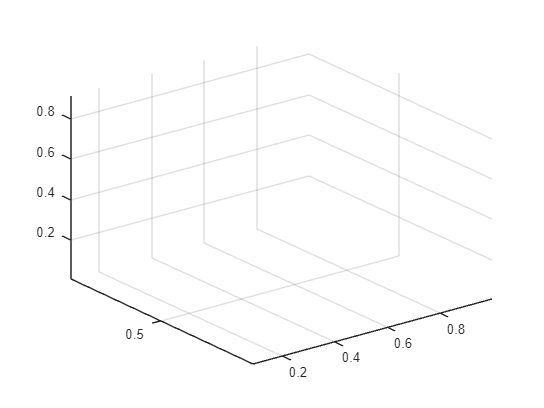

Localization Accuracy: 64.8828%



if task == "localization"
    YScores = predict(net,validation.X);
    YPred = scores2label(YScores,categories(labels.class));
    if iscell(YPred)
        YPred = categorical(YPred);  % Convert to categorical if needed
    end
    
    locs = validation.Y.regression; 

    % Call the classification visualization function
    accuracy = plotClassification(YTrue, YPred, locs); % Pass true labels (YTrue) and predicted labels (YPred)
    
    disp(['Localization Accuracy: ', num2str(accuracy), '%']);
else % positioning
    YPred = predict(net,validation.X);
    meanErr = plotRegression(validation.Y.regression, YPred); % Pass true positions (YTrue) and predicted positions (YPred)
    
    disp(['Positioning Error (Mean Distance): ', num2str(meanErr), ' meters']);
end

Legend handles:
  7×1 Scatter array:

  Scatter
  Scatter
  Scatter
  Scatter
  Scatter
  Scatter
  Scatter

Legend labels:
    {'conference_room'}
    {'desk1'          }
    {'desk2'          }
    {'desk3'          }
    {'desk4'          }
    {'office'         }
    {'storage'        }

# Handles: 7, # Labels: 7



metric = dlPositioningPlotResults(mapFile,validation.Y,YPred,task);